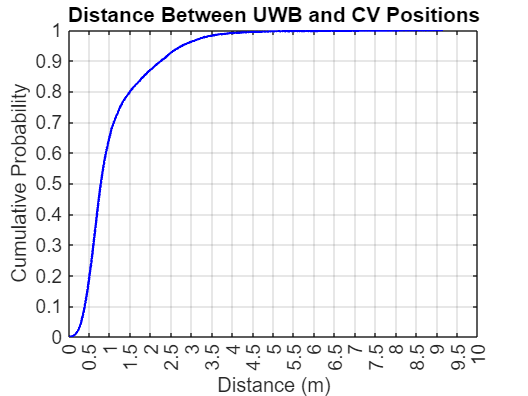

file_id = fopen('every_100ms_uwb_cv_dist.csv');
C = textscan(file_id, '%s%f%s%f%s%f%s%f%s%f', 'Delimiter', ',', 'HeaderLines', 1);
fclose(file_id);

data = deal(C{10});
data2 = data;
cdf1 = cdfplot(data2);
hold on;
set(cdf1,'color','b','LineWidth',1.2);
xlabel('Distance (m)','FontSize',10);
ylabel('Cumulative Probability','FontSize',10);
% here, even the end is 11, the picture only has 10, because no data bigger than 10
xticks(0:0.5:11); 
yticks(0:0.1:1);
%xticklabels([0 10 20 30 40 50 60 70 80 90 100]);

%xlim(gca, [0 20]);
%set(gca, 'xlim', [0 4]);

%legend([cdf1], {'Distance between UWB and CV'}, "Location", "SouthEast");

title('Distance Between UWB and CV Positions');
hold off;